# 实验八 曲线拟合

## 实验目的

- 掌握曲线拟合的最小二乘法原理

- 理解超定方程组的最小二乘法原理

- 通过联系掌握实现最小二乘法曲线拟合的编程技巧

## 实验环境

- 计算机

- MATLAB集成环境

## 实验内容与代码

### 某车间计划加工一批飞机零部件，为了规定工时定额，需要确定加工零件所花费的时间，为此进行了10次实验，收集数据如下：


$$\left\lbrack \begin{array}{cc}
\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack  & \left\lbrack \begin{array}{cccccccccc}
10 & 20 & 30 & 40 & 50 & 60 & 70 & 80 & 90 & 100\\
62 & 68 & 75 & 81 & 89 & 95 & 102 & 108 & 115 & 122
\end{array}\right\rbrack 
\end{array}\right\rbrack$$


- 画出散点图

- 用最小二乘法拟合直线$y=a\cdot x+b$

clc;clear;
x = [10 20 30 40 50 60 70 80 90 100]

x =     10    20    30    40    50    60    70    80    90   100


y = [62 68 75 81 89 95 102 108 115 122]

y =     62    68    75    81    89    95   102   108   115   122


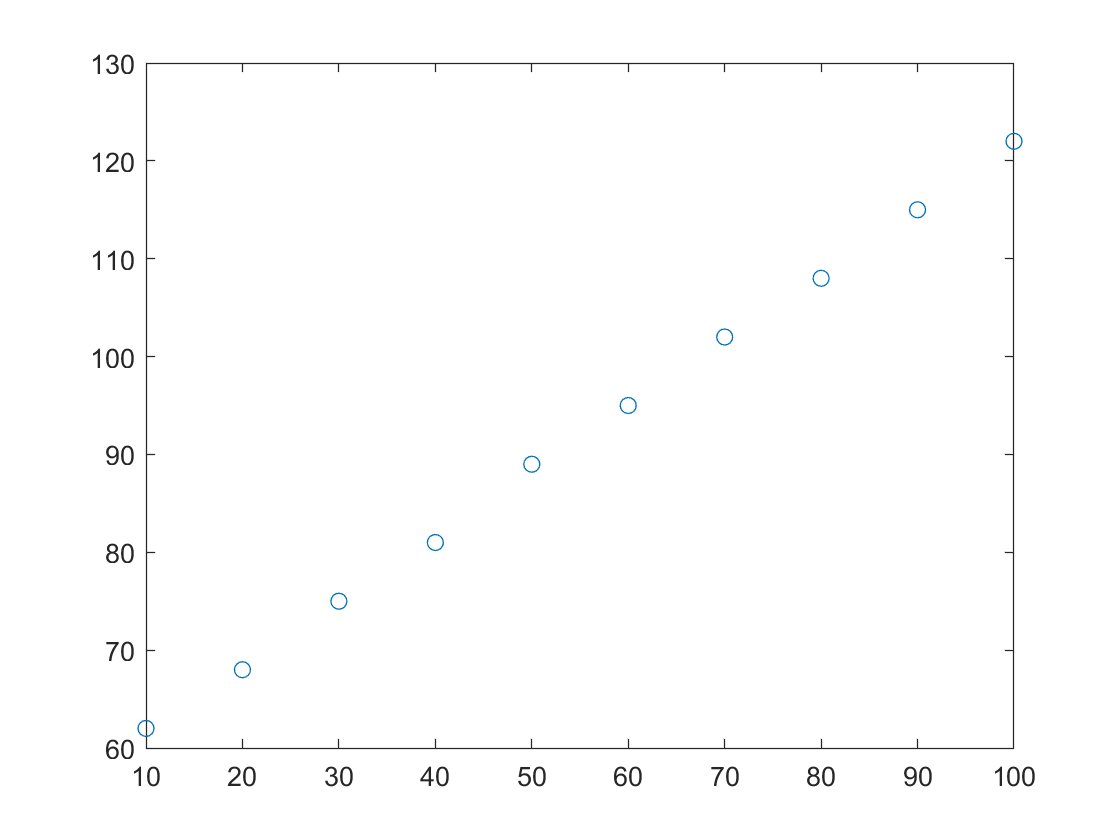

plot(x, y, 'o')

p = polyFit(x, y, 1)

p =     0.6685   54.9333


res = "y = " + p(1) + "x + " + p(2)

res = "y = 0.66848x + 54.9333"

f = polyval(p,x)

f =    61.6182   68.3030   74.9879   81.6727   88.3576   95.0424  101.7273  108.4121  115.0970  121.7818


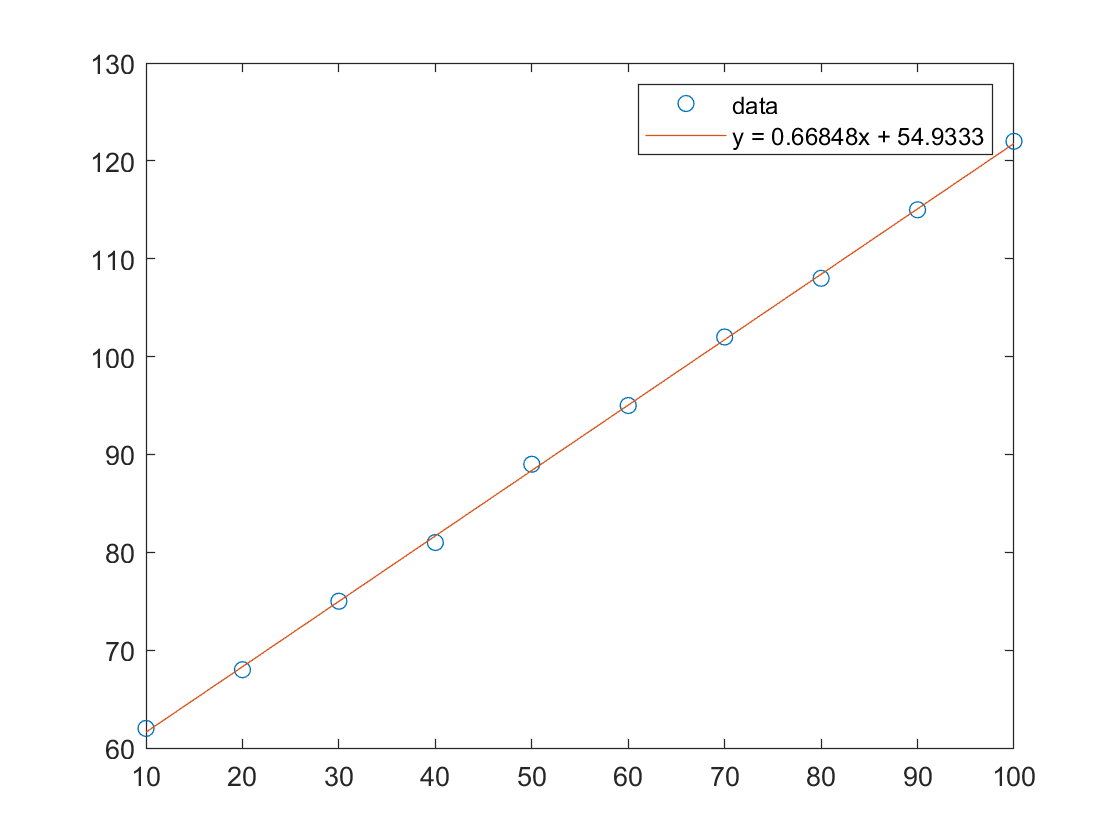

plot(x, y, 'o', x, f, '-')
legend({'data',res})

### 给定一组观察数据，试用最小二乘法拟合这组数据的多项式


$$\left\lbrack \begin{array}{cccccccc}
x & 0\ldotp 0 & 0\ldotp 50 & 0\ldotp 60 & 0\ldotp 70 & 0\ldotp 80 & 0\ldotp 90 & 1\ldotp 00\\
f\left(x\right) & 1\ldotp 0000 & 1\ldotp 75 & 1\ldotp 96 & 2\ldotp 19 & 2\ldotp 44 & 2\ldotp 71 & 3\ldotp 00
\end{array}\right\rbrack$$


- 画出拟合数据点的图形

- 确定用几次的多项次拟合这组数据

- 求$f\left(x\right)$的最小二乘拟合函数

clc;clear;
x = [0 0.5 0.6 0.7 0.8 0.9 1]

x =          0    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


y = [1 1.75 1.96 2.19 2.44 2.71 3]

y =     1.0000    1.7500    1.9600    2.1900    2.4400    2.7100    3.0000


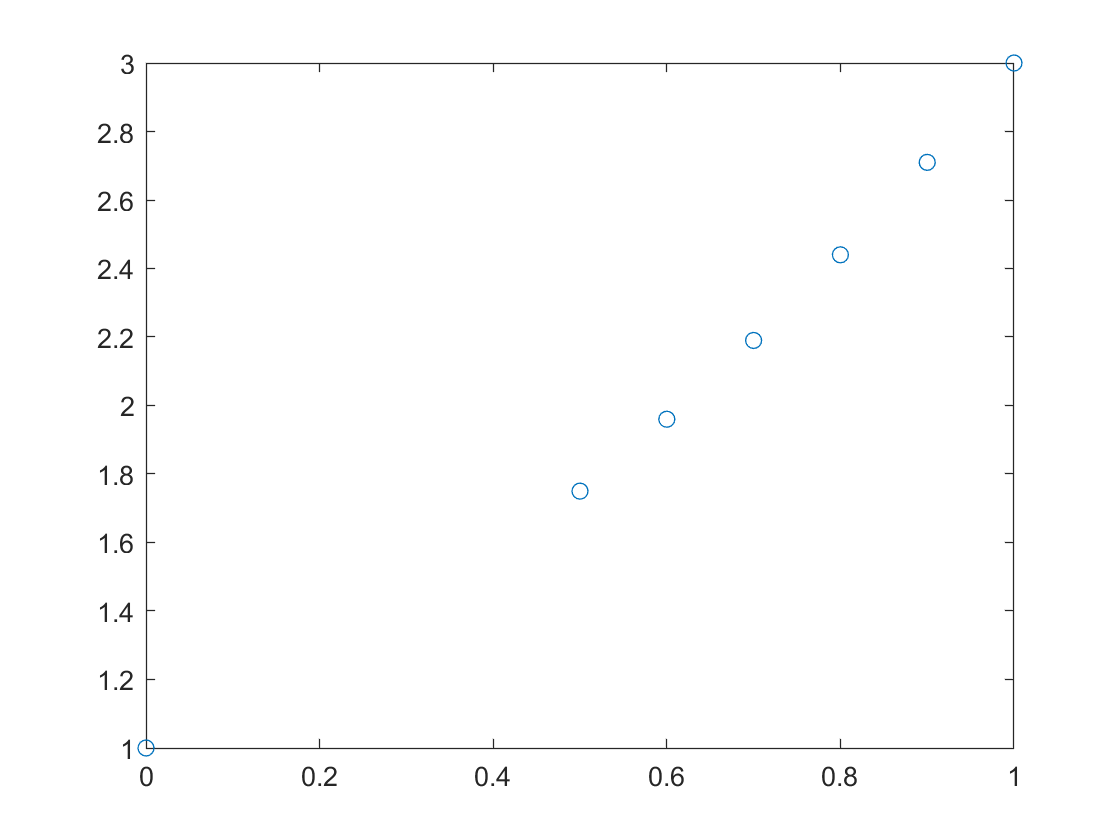

plot(x, y, 'o')

p2 = polyFit(x, y, 2)

p2 =     1.0000    1.0000    1.0000


p3 = polyFit(x, y, 3)

p3 =     0.0000    1.0000    1.0000    1.0000


p4 = polyFit(x, y, 4)

p4 =     0.0000   -0.0000    1.0000    1.0000    1.0000


x1 = 0:0.01:1

x1 =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


f = polyval(p2,x1)

f =     1.0000    1.0101    1.0204    1.0309    1.0416    1.0525    1.0636    1.0749    1.0864    1.0981    1.1100    1.1221    1.1344    1.1469    1.1596    1.1725    1.1856    1.1989    1.2124    1.2261    1.2400    1.2541    1.2684    1.2829    1.2976    1.3125    1.3276    1.3429    1.3584    1.3741    1.3900    1.4061    1.4224    1.4389    1.4556    1.4725    1.4896    1.5069    1.5244    1.5421    1.5600    1.5781    1.5964    1.6149    1.6336    1.6525    1.6716    1.6909    1.7104    1.7301


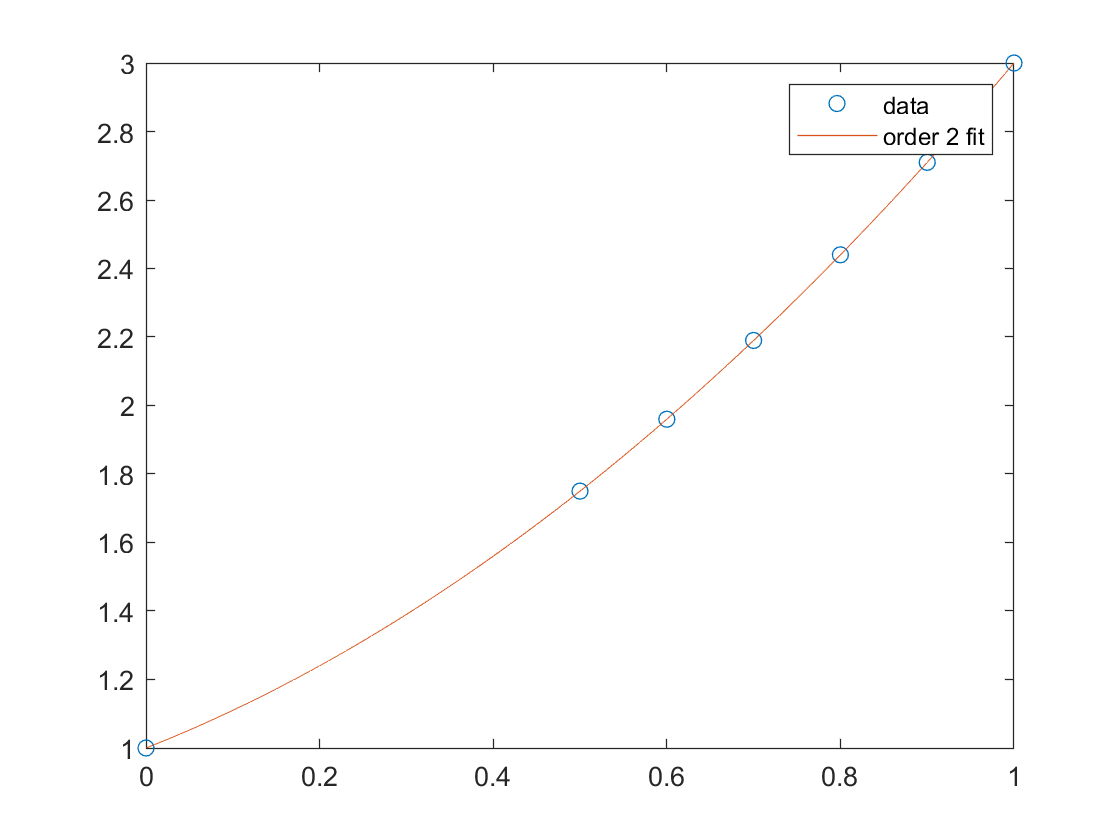

plot(x, y, 'o', x1, f, '-')
legend({'data','order 2 fit'})

由上述结果可知：该函数从2次开始拟合结果相同

则可知，拟合函数为：$f\left(x\right)=x^2 +x+1$

### 此实时脚本中使用的函数：

function [p] = polyFit(x,y,n)
    %POLYFIT Fit polynomial to data.
    %   P = POLYFIT(X,Y,N) finds the coefficients of a polynomial P(X) of
    %   degree N that fits the data Y best in a least-squares sense. P is a
    %   row vector of length N+1 containing the polynomial coefficients in
    %   descending powers, P(1)*X^N + P(2)*X^(N-1) +...+ P(N)*X + P(N+1).
    %
    %   Example: simple linear regression with polyfit
    %
    %     % Fit a polynomial p of degree 1 to the (x,y) data:
    %       x = 1:50;
    %       y = -0.3*x + 2*randn(1,50);
    %       p = polyFit(x,y,1);
    %
    %     % Evaluate the fitted polynomial p and plot:
    %       f = polyval(p,x);
    %       plot(x,y,'o',x,f,'-')
    %       legend('data','linear fit')
    %
    %   Class support for inputs X,Y:
    %      float: double, single
    %
    
    x = x(:);
    y = y(:);
    
    outputClass = superiorfloat(x,y);
    
    % Construct the Vandermonde matrix V = [x.^n ... x.^2 x ones(size(x))]
    V(:,n+1) = ones(length(x),1,class(x));
    for j = n:-1:1
        V(:,j) = x.*V(:,j+1);
    end
    
    % Convert y to the same class as V
    y1 = cast(full(y), class(V));
    
    % Solve least squares problem p = V\y to get polynomial coefficients p.
    [QRfactor, tau, perm, ~] = matlab.internal.decomposition.builtin.qrFactor(V, -2);
    % use nonzero diagonal entries to determin rank for qrSolve.
    rV = sum(abs(getDiag(QRfactor)) ~= 0);
    % QR solve with rank = rV.
    p = matlab.internal.decomposition.builtin.qrSolve(QRfactor, tau, perm, y1, rV);
    
    % Get correct output class
    p = cast(p, outputClass);
    
    p = p.'; % Polynomial coefficients are row vectors by convention.
end
    
function d = getDiag(X)
    % get diagonal entries of X.
    if isvector(X)
        if isempty(X)
            d = X(:);
        else
            d = X(1);
        end
    else
       d = diag(X);
       d = d(:); %handle diag([])
    end
end